close("all"); clear; clc;

time = optvar("time","t","time","s",0);
p = optvar("position","x","position","m",0,1);
theta = optvar("angle","theta","position","rad",deg2rad(180),0);
v = optvar("velocity","v","speed","m/s",0,0);
w = optvar("angular velocity","omega","speed","rad/s",0,0);

states = [
    p;
    theta;
    v;
    w
    ];

force = optvar("force","F","force","N",[],[],-25,25);
controls = force;

x = ocpvars(time,states,controls);

J = ocpcost(x,@(x,u)1 + 0.*u(1,:));

p = [-9.81,0.3,0.5,0.2].';
plant = dyncon(x,@(x,u)invertedPendulumAndCart(x,u,p));

C = ocpcon(x,plant);

prob = ocp(x,J,C);
disp(prob)

============================ Optimal Control Problem ===========================
                                    MINIMISE                                    


$$J=t_{f}$$

                                   SUBJECT TO                                   
=================================== Dynamics ===================================


$$\frac{\partial }{\partial t}x\left(t\right)=v\left(t\right)$$

$$\frac{\partial }{\partial t}\theta \left(t\right)=\omega \left(t\right)$$

$$\frac{\partial }{\partial t}v\left(t\right)=-\frac{30\,\sin\left(\theta \left(t\right)\right)\,{\omega \left(t\right)}^{2}+500\,F\left(t\right)-981\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{50\,\left(2\,{\cos\left(\theta \left(t\right)\right)}^{2}-7\right)}$$

$$\frac{\partial }{\partial t}\omega \left(t\right)=\frac{60\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\omega \left(t\right)}^{2}-6867\,\sin\left(\theta \left(t\right)\right)+1000\,\cos\left(\theta \left(t\right)\right)\,F\left(t\right)}{30\,\left(2\,{\cos\left(\theta \left(t\right)\right)}^{2}-7\right)}$$

============================== Control path bounds =============================


$$-25\leq F\left(t\right)$$

$$F\left(t\right)\leq 25$$

ns = 20;
M = ns + 1;

x0 = zeros(4,M);
u0 = zeros(1,M);
y0 = [x0;u0];
z0 = [10;y0(:)];
prog = transcribe(@Trapezoidal,prob,z0);

opts = optimoptions( ...
    "fmincon", ...
    "MaxFunctionEvaluations",1E06, ...
    "MaxIterations",1E04 ...
    );
tic;
prog.solve(opts);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc; 

Elapsed time is 2.832449 seconds.


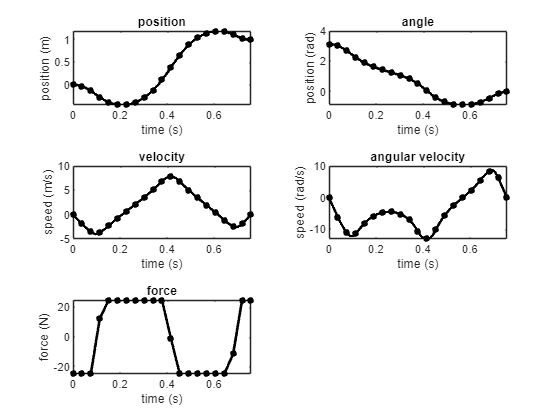

fig = prog.plot(3,2);